# Demo 01: 3D CSI Phantom data

## data download and setup

add paths and set up data paths. Download in vivo data  (3.8 GB "sub-01-DMI.tar.gz")  from [zenodo.org (DOI: 10.5281/zenodo.14652737)](https://doi.org/10.5281/zenodo.14652737).

% add all dependencies
addpath(genpath('/ptmp/pvalsala/Packages/mapVBVD'))
addpath(genpath('/ptmp/pvalsala/Packages/DeuteMetCon'))
addpath(genpath('/ptmp/pvalsala/Packages/OXSA'))
addpath('/ptmp/pvalsala/Packages/spm12/')

% set up data folder
sn='/ptmp/pvalsala/deuterium/dataForPublication/sub-01-DMI';
dirst_csi=dir(fullfile(sn,"*rpcsi_fid*.dat"));


## load metabolite structure 

The chemical shifts, measured relaxation times and labels of all four metabolites in phantom is organised in a array of struct

% second argument is the frequency offset of water in Hz
metabolites=getMetaboliteStruct('invivo',0);


## `Inputs and flags for metabolite mapping`

`All functions and data required for all data processing steps like image reconstruciton, coil combination and spectral seperation were encapsualted in a single class `MetCon_CSI.m`. All inputs and flags except the raw data file is a name-value pair as described below.`

% | name                        | description                                                | default   | possible options                                                 |
% |-----------------------------|------------------------------------------------------------|-----------|------------------------------------------------------------------|
% | 'metabolites'               | struct array with definition of metabolites                | []        | see getMetaboliteStruct.m function                               |
% | 'fm'                        | 1H fieldmap in rad/s                                       | []        | 3D numeric matrix or 'IDEAL'                                     |
% | 'csm'                       | coil maps                                                  | []        | 3D numeric matrix                                                |
% | 'mask'                      | mask for spectral separation                               | []        | 3D logical matrix                                                |
% | 'doDenosing'                | SVD denoising                                              | 0         | scalar No of components, -1 for debug                            |
% | 'Solver'                    | spectral separation method                                 | 'IDEAL'   | {'phaseonly','pinv','IDEAL','IDEAL-modes','AMARES','LorentzFit'} |
% |                             |                                                            |           | 'phaseonly'- linear method with only phase evolution             |
% |                             |                                                            |           | 'pinv'- linear method with full signal model                     |
% |                             |                                                            |           | 'IDEAL'- iterative IDEAL algorithm                               |
% |                             |                                                            |           | 'IDEAL-modes'-IDEAL algorithm for phase cycled data              |
% |                             |                                                            |           | 'AMARES'- AMARES spectral fitting                                |
% |                             |                                                            |           | 'LorentzFit'- lorentzian spectral fitting                        |
% | 'parfor'                    | flag to use parfor                                         | true      | boolean                                                          |
% | 'doZeroPad'                 | zero pad factor                                            | [1 1 1 0] | positive scalar array [3 physical axis x 1 time]                 |
% | 'doSmoothFM','maxit'        | IDEAL flags: fieldmap smooth factor and maximum iterations | 1,10      | scalar(+ve: gaussian, -ve: median),postive scalar                |
% | 'doPhaseCorr'               | phase correction mode                                      | 'none'    | {'none','Manual','Burg'}                                         |
% | 'CoilSel','PCSel','EchoSel' | arrays to picks some of coils, time points and phasecyles. | 1:max()   | positive integer array                                           |
% |'doNoiseDecorr'              | flag to perform noise decorrelation                        | true      | boolean                                                          |
% | 'doCoilCombine'             | coil combine mode                                          | 'adapt1'  | {'none','sos','adapt1','wsvd'}                                   |

CSI_setting={'metabolites',metabolites,'doPhaseCorr','none','parfor',true,...
    'doCoilCombine','adapt1','doZeropad',[0.5 0.5 0.5 0],'mask',[],'Solver','IDEAL','fm',[]};

## Process data

CSI_filename=fullfile(sn,dirst_csi(end).name);
mcobj_fisp=MetCon_CSI(CSI_filename,CSI_setting{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   661.3 MB read in    9 s
starting reco
initial CSI data size:           10   25   25   25  256
final CSI data size:           10   51   51   51  256
reco  time =   16.9 s
estimating field map(1/2) 
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 36 workers.
estimating metabolities(2/2) 
Metabolite mapping time =   66.1 s


### Ploting

After image reconstruciton and spectral seperation, metbolite amplitudes are store in mcobj_csi.Metcon. The 4D Metcon matrix and 2H field map estimated by IDEAL algorithm can be quickly visualized with `PlotResults` method.

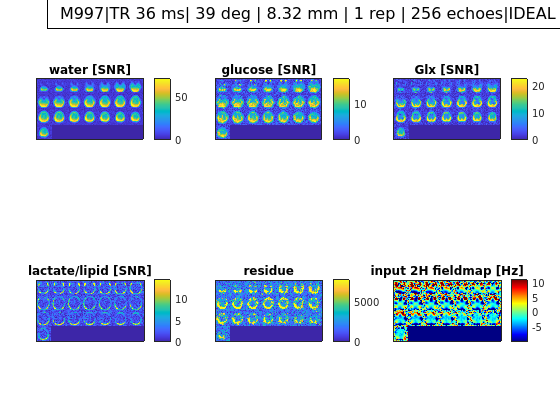

mcobj_fisp.PlotResults()

## Data structure of Metcon_CSI object

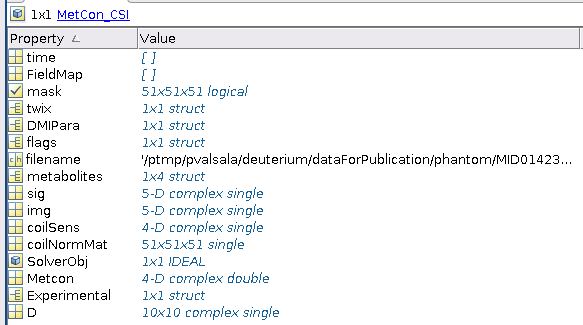

 Where 

- DMIPara are the important sequence parameters parsed from twix with `getDMIPara.m` fucntion

- flags contains all the processing flags

- sig - averaged signal [CHAx LIN  xSEG x PAR   x COL (time) x REP(PhaseCylces)]

- img - reconstructed image [CHA x 3 physical dimension x time]

- Metcon - Metabolite amplitudes [CHA x 3 physical dimension x time]

- Experimental- contains all experimental outputs of processing (fieldmap, residue, other fit parameters, fit quality)

- D- noise decorrelation matrix.

## Processing CSI-bSSFP data

We use `IDEAL-modes` for phase-cycled data for SNR optimallity. Other Solver flags use averaged phase-cyles volumes

 CSI_setting_ssfp={'metabolites',metabolites,'doPhaseCorr','none','parfor',true,...
     'doCoilCombine','adapt1','doZeropad',[0.5 0.5 0.5 0],'mask',[],'Solver','IDEAL-modes','fm','IDEAL'};
 dirst_csi_ssfp=dir(fullfile(sn,"*rpcsi_ssfp*.dat"));
CSI_filename=fullfile(sn,dirst_csi_ssfp(1).name);
mcobj_ssfp=MetCon_CSI(CSI_filename,CSI_setting_ssfp{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   335.9 MB read in   10 s
starting reco
initial CSI data size:           10  25  25  25  64   4
final CSI data size:           10  51  51  51  64   4
reco  time =   17.5 s
estimating field map(1/2) 
estimating metabolities(2/2) 
Metabolite mapping time =   25.1 s


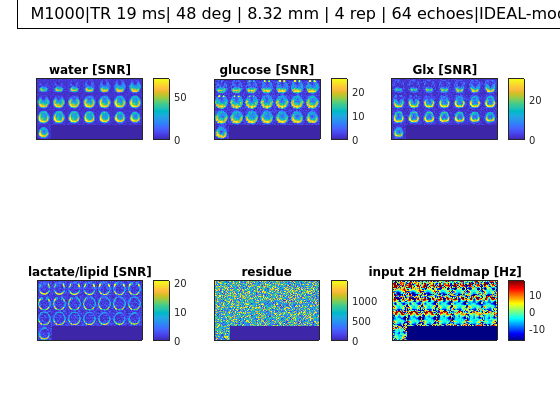

mcobj_ssfp.PlotResults()

## Overlay plot with anatomy

we need spm12 in path for reslicing. We plot the third metabolite (Glx) over skull stripped anatomy.

%addpath('/ptmp/pvalsala/Packages/spm12/')
anat_tra=fullfile(sn,'anat/brain_tra.nii');

% export NIFTI volumes of all outputs (average image, metabolite amplitude in SNR unit and mM)
pn=fullfile(sn,sprintf('proc/csi_%s',datetime('today','Format','yyyyMMMdd')));
mkdir(pn);

niiFileName_fisp=mcobj_fisp.WriteImages(pn);
niiFileName_ssfp=mcobj_ssfp.WriteImages(pn);
% reslice the metabolite amplitude to anatomy!
resliced_metcon=myspm_reslice(anat_tra,dir(fullfile(pn,'Metcon_SNR_*csi*.nii')),'nearest','rt');

reslicing 2 volumes: Metcon_SNR_m00997_rpcsi_fid_Stan_res15.6_moreoptimal_IDEAL_none.nii
Metcon_SNR_m01000_rpcsi_ssfp_Stan25_15.6mm_IDEAL-modes_none.nii


------------------------------------------------------------------------
14-Apr-2025 16:18:48 - Running job #1
------------------------------------------------------------------------
14-Apr-2025 16:18:48 - Running 'Coregister: Reslice'

SPM12: spm_reslice (v7141)                         16:18:48 - 14/04/2025
Completed                               :          16:18:49 - 14/04/2025
14-Apr-2025 16:18:49 - Done    'Coregister: Reslice'
14-Apr-2025 16:18:49 - Done



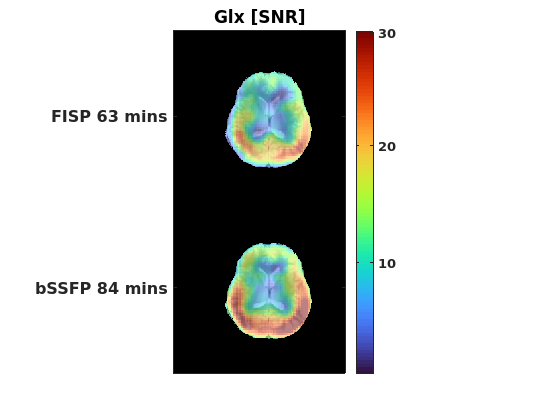

%% Overlay plot
clim_glx=[0 30];
figure,
overlayplot(dir(anat_tra),dir(fullfile(pn,'rt*.nii')),'MetIdx',3,'SlcSel',15, ...
    'transform',@(x) flip(permute(x,[2 1 3 4 5]),1),...
  'cax',clim_glx,'cax_im',[0,0.9],'cmap',turbo,'alpha_overlay',0.5);
title([metabolites(3).name,' [SNR]']) % 'MetIdx',3
yticklabels({sprintf('FISP %d mins',mcobj_fisp.getMinutesAfterIntake('08:36')),...
    sprintf('bSSFP %d mins',mcobj_ssfp.getMinutesAfterIntake('08:36'))});

%make your own colorbar
cb_handle=colorbar;
cb_handle.Visible='off';
ax2 = axes('Position',cb_handle.Position);
imagesc(linspace(0,1,100)'),colormap(ax2,'turbo')
set(ax2,'YAxisLocation','right','FontSize',10,'FontWeight','bold','YDir','normal')
yticks(round(linspace(0,100,4)))
yticklabels(round(linspace(0,1,4)*clim_glx(2),1))
xticks([])

## Other miscallaneous methods which can be useful

% The metabolite amplitudes can be normalized into SNR 
metcon_SNR= mcobj_fisp.getNormalized();

% method and quantified into mM with 10 mM water reference using `getmM`
% fucntion. (Doesn't work in phantom as 10mM water reference is not there!)
metcon_mM= mcobj_fisp.getmM();

% export NIFTI volumes of all outputs (average image, metabolite amplitude in SNR unit and mM)
pn=fullfile(sn,sprintf('proc/csi_%s',datetime('today','Format','yyyyMMMdd')));
niiFileName=mcobj_fisp.WriteImages(pn);

%plot the k-space weighting and PSF to get realistic voxel size (FW64%)
voxel_size_mm= getPSF_CSI(mcobj_fisp.twix);
% it is non-sense for phantom scans but still!
Intake_time_mins=mcobj_fisp.getMinutesAfterIntake('08:00');


### Debug (only for AMARES and Lorentzian solver so far)

Useful for checking data at a particular voxel index. [38,30,34] is gray matter voxel.

Iterations = 22.
Norm of residual = 521.582
Norm of the data = 1005.033
resNormSq / dataNormSq = 0.519
zeroOrderPhaseRad = 2.559


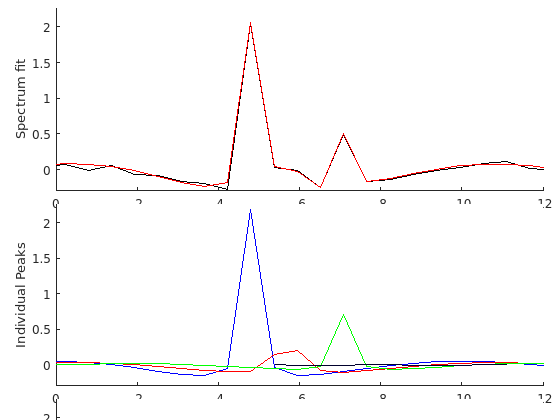

    chemShift: [0.0089 -0.8759 -2.3246 -3.1511]
    linewidth: [10.4984 22.3310 12.1608 2.0022]
    amplitude: [5.2357 1.9673 1.8423 0.0327]
        phase: [146.6341 146.6341 146.6341 146.6341]
        sigma: [0 0 0 0]



mcobj_fisp.demoFit([38,30,34])